clear all;
close all;
clc;

addpath("data");
addpath("funzioni");
run("estraz_dati.m");

Tabella sincronizzata creata con successo:
    Tempo [s]     X_HTC [m]      Y_HTC [m]      Z_HTC [m]     DegX_HTC [deg]    DegY_HTC [deg]    DegZ_HTC [deg]     X_RS [m]      Y_RS [m]      Z_RS [m]    DegX_RS [deg]    DegY_RS [deg]    DegZ_RS [deg]    OmegaXl_IMU [deg/s]    OmegaXr_IMU [deg/s]    OmegaXm_IMU [deg/s]    OmegaYl_IMU [deg/s]    OmegaYr_IMU [deg/s]    OmegaYm_IMU [deg/s]    OmegaZl_IMU [deg/s]    OmegaZr_IMU [deg/s]    OmegaZm_IMU [deg/s]    AccXl_IMU [m/s^2]    AccXr_IMU [m/s^2]    AccXm_IMU [m/s^2]    AccYl_IMU [m/s^2]    AccYr_IM

## Encoders Data extraction

MOTION_START = 125;

Ntic_R = table2array(T_synced(1:end,"Right_ENC [tic]"));
Ntic_L = table2array(T_synced(1:end,"Left_ENC [tic]"));

%Tic incremento at each step steps
Ntic_R = diff(Ntic_R);
Ntic_L = diff(Ntic_L);

## IMU Data extraction

% % Angoular Velocity
% omega = table2array(T_synced(MOTION_START:end-1, "OmegaZm_IMU [deg/s]"));
% 
% % Linear Acceleration
% Acc_IMU_m  = table2array(T_synced(MOTION_START:end-1, "AccZm_IMU [m/s^2]"));
% Acc_IMU_l  = table2array(T_synced(MOTION_START:end-1, "AccZl_IMU [m/s^2]"));
% Acc_IMU_r  = table2array(T_synced(MOTION_START:end-1, "AccZr_IMU [m/s^2]"));
% % Time Vector
% Time = table2array(T_synced(MOTION_START:end-1, "Tempo [s]"));
% 
% a = [Acc_IMU_l, Acc_IMU_m, Acc_IMU_r ];
% 
% b = diff(Acc_IMU_m);
% 
% Media_Accel_X = mean(a, 2);


## HTC data extraction

x_HTC = table2array(T_synced(1:end-1, "X_HTC [m]"));
y_HTC = table2array(T_synced(1:end-1, "Y_HTC [m]"));
theta_HTC = table2array(T_synced(1:end-1, "DegZ_HTC [deg]")); %deg around Z
theta_HTC = unwrap(theta_HTC); %to solve phase problems
theta_HTC = deg2rad(theta_HTC); %rad

## State transition model

**NOTE: **for all the nomenclature see paper [https://ieeexplore.ieee.org/document/10777435](https://ieeexplore.ieee.org/document/10777435))

Here are reported:

-  the odometry equations (from  Antonelli and Chiaverini) 

- The matrix F of the EKF 

- The covariance matrix of the process (odometry) Q

The last 2 are computed in using the function print_syst().

Q = print_syst();

$$x\_new = x+\frac{\pi \,\cos\left(\theta -\frac{\pi \,\left({\mathrm{NTic}}_{L}\,\mathrm{Rl}-{\mathrm{NTic}}_{R}\,\mathrm{Rr}\right)}{{\mathrm{Enc}}_{\mathrm{res}}\,b}\right)\,\left({\mathrm{NTic}}_{L}\,\mathrm{Rl}+{\mathrm{NTic}}_{R}\,\mathrm{Rr}\right)}{{\mathrm{Enc}}_{\mathrm{res}}}$$

$$y\_new = y+\frac{\pi \,\sin\left(\theta -\frac{\pi \,\left({\mathrm{NTic}}_{L}\,\mathrm{Rl}-{\mathrm{NTic}}_{R}\,\mathrm{Rr}\right)}{{\mathrm{Enc}}_{\mathrm{res}}\,b}\right)\,\left({\mathrm{NTic}}_{L}\,\mathrm{Rl}+{\mathrm{NTic}}_{R}\,\mathrm{Rr}\right)}{{\mathrm{Enc}}_{\mathrm{res}}}$$

$$theta\_new = \theta -\frac{2\,\pi \,\left({\mathrm{NTic}}_{L}\,\mathrm{Rl}-{\mathrm{NTic}}_{R}\,\mathrm{Rr}\right)}{{\mathrm{Enc}}_{\mathrm{res}}\,b}$$

$$J\_symbolic = \left(\begin{array}{ccc} 1 & 0 & -\frac{\pi \,\sin\left(\theta -\frac{\pi \,\left({\mathrm{NTic}}_{L}\,\mathrm{Rl}-{\mathrm{NTic}}_{R}\,\mathrm{Rr}\right)}{{\mathrm{Enc}}_{\mathrm{res}}\,b}\right)\,\left({\mathrm{NTic}}_{L}\,\mathrm{Rl}+{\mathrm{NTic}}_{R}\,\mathrm{Rr}\right)}{{\mathrm{Enc}}_{\mathrm{res}}}\\ 0 & 1 & \frac{\pi \,\cos\left(\theta -\frac{\pi \,\left({\mathrm{NTic}}_{L}\,\mathrm{Rl}-{\mathrm{NTic}}_{R}\,\mathrm{Rr}\right)}{{\mathrm{Enc}}_{\mathrm{res}}\,b}\right)\,\left({\mathrm{NTic}}_{L}\,\mathrm{Rl}+{\mathrm{NTic}}_{R}\,\mathrm{Rr}\right)}{{\mathrm{Enc}}_{\mathrm{res}}}\\ 0 & 0 & 1 \end{array}\right)$$

Q

Q = 1.0e-03 *

    0.1327         0         0
         0    0.1327         0
         0         0    0.3201


## Measurement Model HTC

Here the covariance matrix of the data from the HTC is derived.

% Measurement Matrix
H = eye(3,3);

% Data form HTC with the robot still
Z_still = [x_HTC(1:MOTION_START)  y_HTC(1:MOTION_START) theta_HTC(1:MOTION_START)];

sigma_x_HTC = var(x_HTC(1:MOTION_START));
sigma_y_HTC = var(y_HTC(1:MOTION_START));
sigma_theta_HTC = var(theta_HTC(1:MOTION_START));

variances_vector_HTC = [sigma_x_HTC, sigma_y_HTC, sigma_theta_HTC];

R_HTC = diag(variances_vector_HTC)

R_HTC = 1.0e-07 *

    0.0948         0         0
         0    0.1176         0
         0         0    0.2188


This with the assumption of statistically independent measurements. In reality the covariance matrix is this one:

cov(Z_still)

ans = 1.0e-07 *

    0.0948    0.0516    0.0548
    0.0516    0.1176    0.0287
    0.0548    0.0287    0.2188


## Kalman Filter

In this case only HTC is used for the Update step of the EKF

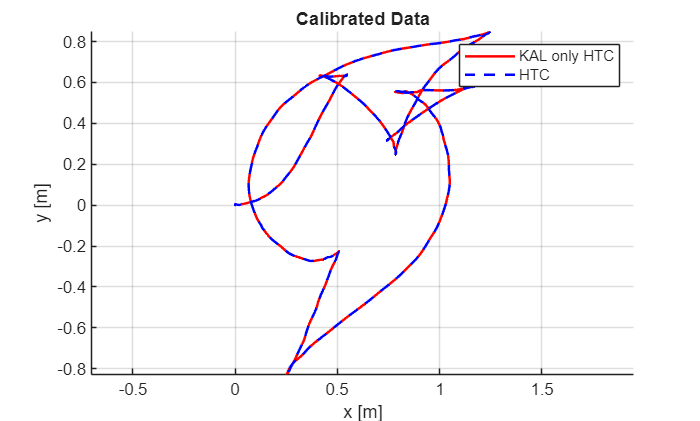

n = length(Ntic_R);
b= 0.8291; 
Rr = 0.0873;
Rl = 0.0857;
Enc_res = 4096;


% R_HTC = diag(variances_vector_HTC)*10^100


theta_incr = zeros(1, n);

X_prior = zeros(3, n); % [x, y, theta]
X_post = zeros(3, n);

Z_HTC = [x_HTC' ; y_HTC' ; theta_HTC'];

P = R_HTC; %Initialization of P

for i = 1:n-1
    
    % Prediction
    theta_incr(i+1) = 2*pi * (Ntic_R(i)*Rr-Ntic_L(i)*Rl) / (Enc_res*b);
    
    X_prior(1, i+1) = X_post(1, i) + pi * ((Ntic_R(i)*Rr+Ntic_L(i)*Rl) / Enc_res) * cos(X_post(3, i) + theta_incr(i)/2);
    X_prior(2, i+1) = X_post(2, i) + pi * ((Ntic_R(i)*Rr+Ntic_L(i)*Rl) / Enc_res) * sin(X_post(3, i) + theta_incr(i)/2);
    X_prior(3, i+1) = X_post(3, i) + theta_incr(i);
    
    F = [ 1    0    -pi * ((Ntic_R(i)*Rr+Ntic_L(i)*Rl) / Enc_res) * sin(X_post(3, i) + theta_incr(i)/2);            
          0    1     pi * ((Ntic_R(i)*Rr+Ntic_L(i)*Rl) / Enc_res) * cos(X_post(3, i) + theta_incr(i)/2); 
          0    0                               1                                                  ];

    P = F*P*F' + Q;

    % Update
    K = (P * H') / (H * P * H' + R_HTC);
    X_post(:,i+1) = X_prior(:,i+1) + K*(Z_HTC(:,i+1) - X_prior(:,i+1));
    P = (eye(3) - K * H) * P;
    
end 

figure(1); clf; hold on; grid on;
plot(X_post(1,:), X_post(2,:), 'LineWidth', 1.5, "Color", "r");
plot(x_HTC, y_HTC, 'LineWidth', 1.5, "Color", "b", "LineStyle","--");
xlabel('x [m]');
ylabel('y [m]');
title('Calibrated Data');
legend('KAL only HTC', 'HTC');
axis("equal");

## Real Sense Data

Now we also analize the RS data

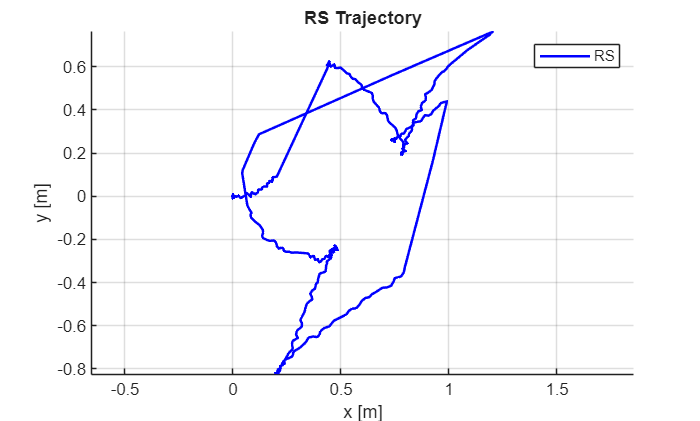

% RS data extraction
x_RS = table2array(T_synced(1:end-1, "X_RS [m]"));
x_RS(1) = 0; % was NaN
y_RS = table2array(T_synced(1:end-1, "Y_RS [m]"));
y_RS(1) = 0; % was NaN
theta_RS = table2array(T_synced(1:end-1, "DegZ_RS [deg]")); %deg around Z
theta_RS = unwrap(theta_RS); %to solve phase problems
theta_RS = deg2rad(theta_RS); %rad
theta_RS(1) = 0; % was NaN

figure(2); clf; hold on; grid on;
plot(x_RS, y_RS, 'LineWidth', 1.5, "Color", "b");
xlabel('x [m]');
ylabel('y [m]');
title('RS Trajectory');
legend('RS');
axis("equal");

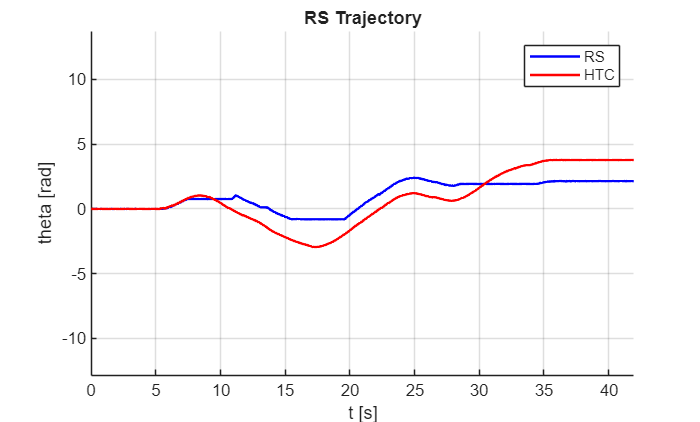

t = table2array(T_synced(1:end-1, "Tempo [s]"));

figure(3); clf; hold on; grid on;
plot(t, theta_RS, 'LineWidth', 1.5, "Color", "b");
plot(t, theta_HTC, 'LineWidth', 1.5, "Color", "r");
xlabel('t [s]');
ylabel('theta [rad]');
title('RS Trajectory');
legend('RS', 'HTC');
axis("equal");

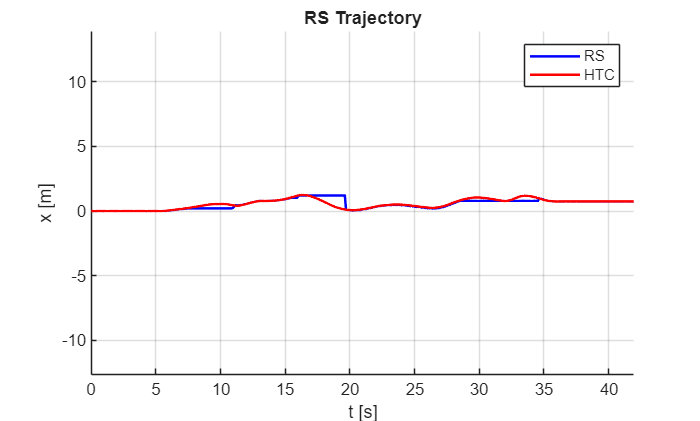

figure(4); clf; hold on; grid on;
plot(t, x_RS, 'LineWidth', 1.5, "Color", "b");
plot(t, x_HTC, 'LineWidth', 1.5, "Color", "r");
xlabel('t [s]');
ylabel('x [m]');
title('RS Trajectory');
legend('RS', 'HTC');
axis("equal");

figure(5); clf; hold on; grid on;
plot(t, y_RS, 'LineWidth', 1.5, "Color", "b");
plot(t, y_HTC, 'LineWidth', 1.5, "Color", "r");
xlabel('t [s]');

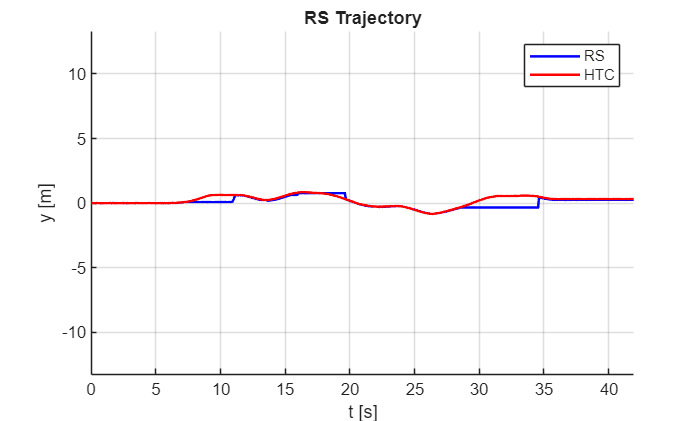

ylabel('y [m]');
title('RS Trajectory');
legend('RS', 'HTC');
axis("equal");

## Measurement Model RS

Here the covariance matrix of the data from the RS is derived.

sigma_x_RS = var(x_RS(1:MOTION_START));
sigma_y_RS= var(y_RS(1:MOTION_START));
sigma_theta_RS = var(theta_RS(1:MOTION_START));

variances_vector_RS = [sigma_x_RS, sigma_y_RS, sigma_theta_RS];

R_RS = diag(variances_vector_RS) 

R_RS = 1.0e-04 *

    0.0009         0         0
         0    0.0659         0
         0         0    0.1160


## EKF Using both RS & HTC

Now we implement the EKF with 2 update steps: one for the HTC data one fot the RS data

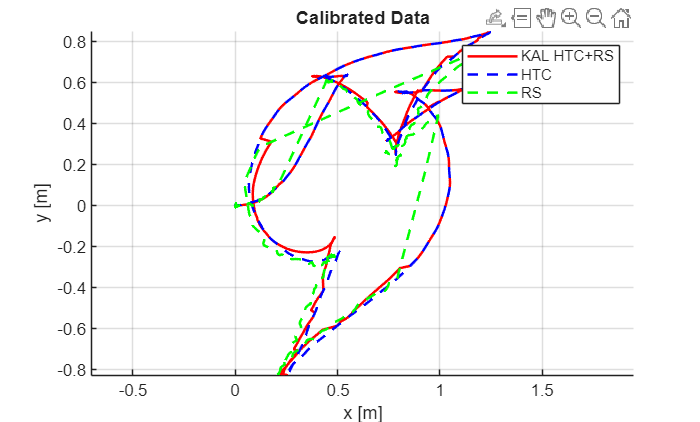

n = length(Ntic_R);
b= 0.8291; 
Rr = 0.0873;
Rl = 0.0857;
Enc_res = 4096;

theta_incr = zeros(1, n);

X_prior = zeros(3, n); % [x, y, theta]
X_post = zeros(3, n);

Z_HTC = [x_HTC' ; y_HTC' ; theta_HTC'];
Z_RS = [x_RS' ; y_RS' ; theta_RS'];

P = R_HTC; %Initialization of P

for i = 1:n-1
    
    % Prediction
    theta_incr(i+1) = 2*pi * (Ntic_R(i)*Rr-Ntic_L(i)*Rl) / (Enc_res*b);
    
    X_prior(1, i+1) = X_post(1, i) + pi * ((Ntic_R(i)*Rr+Ntic_L(i)*Rl) / Enc_res) * cos(X_post(3, i) + theta_incr(i)/2);
    X_prior(2, i+1) = X_post(2, i) + pi * ((Ntic_R(i)*Rr+Ntic_L(i)*Rl) / Enc_res) * sin(X_post(3, i) + theta_incr(i)/2);
    X_prior(3, i+1) = X_post(3, i) + theta_incr(i);
    
    F = [ 1    0    -pi * ((Ntic_R(i)*Rr+Ntic_L(i)*Rl) / Enc_res) * sin(X_post(3, i) + theta_incr(i)/2);            
          0    1     pi * ((Ntic_R(i)*Rr+Ntic_L(i)*Rl) / Enc_res) * cos(X_post(3, i) + theta_incr(i)/2); 
          0    0                               1                                                  ];

    P = F*P*F' + Q;

    % Update 1: HTC
    K1 = (P * H') / (H * P * H' + R_HTC);
    X_post(:,i+1) = X_prior(:,i+1) + K1*(Z_HTC(:,i+1) - X_prior(:,i+1));
    P = (eye(3) - K1 * H) * P;

    % Update 2: Rs
    if (Z_RS(:, i+1) - Z_RS(:, i) ~= 0)
        K2 = (P * H') / (H * P * H' + R_RS);
        X_post(:,i+1) = X_prior(:,i+1) + K2*(Z_RS(:,i+1) - X_prior(:,i+1));
        P = (eye(3) - K2 * H) * P;
    end
end 

figure(6); clf; hold on; grid on;
plot(X_post(1,:), X_post(2,:), 'LineWidth', 1.5, "Color", "r");
plot(x_HTC, y_HTC, 'LineWidth', 1.5, "Color", "b", "LineStyle","--");
plot(x_RS, y_RS, 'LineWidth', 1.5, "Color", "g", "LineStyle","--");
xlabel('x [m]');
ylabel('y [m]');
title('Calibrated Data');
legend('KAL HTC+RS', 'HTC', 'RS');
axis("equal");

## EKF Using only RS 

Now we implement the EKF with only RS data.

n = length(Ntic_R);
b= 0.8291; 
Rr = 0.0873;
Rl = 0.0857;
Enc_res = 4096;

theta_incr = zeros(1, n);

X_prior = zeros(3, n); % [x, y, theta]
X_post = zeros(3, n);

Z_HTC = [x_HTC' ; y_HTC' ; theta_HTC'];
Z_RS = [x_RS' ; y_RS' ; theta_RS'];

P = R_HTC; %Initialization of P

%TRY TO BALANCE COV MATRICES (BACAUSE RS DATA SUCKS)
Q_try = Q

Q_try = 1.0e-03 *

    0.1327         0         0
         0    0.1327         0
         0         0    0.3201


R_RS = diag(variances_vector_RS)*10^10 

R_RS = 1.0e+05 *

    0.0090         0         0
         0    0.6585         0
         0         0    1.1599


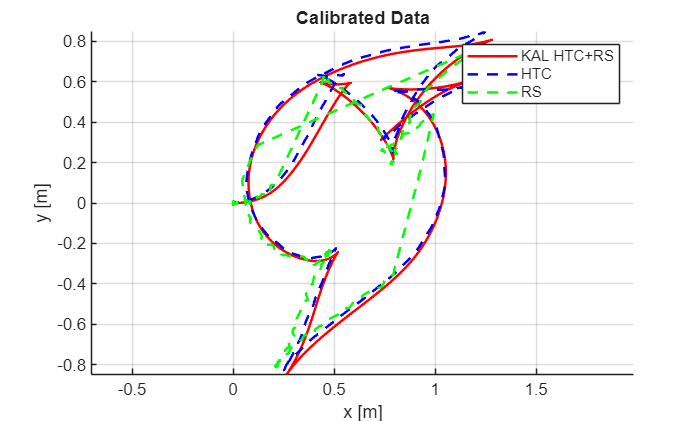

for i = 1:n-1
    
    % Prediction
    theta_incr(i+1) = 2*pi * (Ntic_R(i)*Rr-Ntic_L(i)*Rl) / (Enc_res*b);
    
    X_prior(1, i+1) = X_post(1, i) + pi * ((Ntic_R(i)*Rr+Ntic_L(i)*Rl) / Enc_res) * cos(X_post(3, i) + theta_incr(i)/2);
    X_prior(2, i+1) = X_post(2, i) + pi * ((Ntic_R(i)*Rr+Ntic_L(i)*Rl) / Enc_res) * sin(X_post(3, i) + theta_incr(i)/2);
    X_prior(3, i+1) = X_post(3, i) + theta_incr(i);
    
    F = [ 1    0    -pi * ((Ntic_R(i)*Rr+Ntic_L(i)*Rl) / Enc_res) * sin(X_post(3, i) + theta_incr(i)/2);            
          0    1     pi * ((Ntic_R(i)*Rr+Ntic_L(i)*Rl) / Enc_res) * cos(X_post(3, i) + theta_incr(i)/2); 
          0    0                               1                                                  ];

    P = F*P*F' + Q;


    % Update: RS
    if (Z_RS(:, i+1) - Z_RS(:, i) ~= 0)
        K2 = (P * H') / (H * P * H' + R_RS);
        X_post(:,i+1) = X_prior(:,i+1) + K2*(Z_RS(:,i+1) - X_prior(:,i+1));
        P = (eye(3) - K2 * H) * P;
    else
        X_post(:,i+1) = X_prior(:,i+1);
    end

end 

figure(7); clf; hold on; grid on;
plot(X_post(1,:), X_post(2,:), 'LineWidth', 1.5, "Color", "r");
plot(x_HTC, y_HTC, 'LineWidth', 1.5, "Color", "b", "LineStyle","--");
plot(x_RS, y_RS, 'LineWidth', 1.5, "Color", "g", "LineStyle","--");
xlabel('x [m]');
ylabel('y [m]');
title('Calibrated Data');
legend('KAL HTC+RS', 'HTC', 'RS');
axis("equal");